# P2. Vehicle Lateral Dynamics

Vehicle Control Systems

Degree in Electronics, Robotics and Mechatronics Engineering

University of Malaga

Created by: David Rodríguez Martínez

Last updated: 28 September 2026

### Introduction and objectives

This file contains the coursework instructions and code blocks to complete. Extend the P1 race-car model with longitudinal and lateral dynamics while retaining the P1 longitudinal control functions.

This exercise requires the lateral equation of motion developed in Block 2 and both kinematic and dynamic bicycle models.

After completing this exercise, you should be able to:

- Implement the kinematic bicycle model, which is purely geometric without sliding, and the dynamic model using tyre forces and cornering stiffness. Together they extend P1's longitudinal model to capture lateral dynamics.

- Simulate a simplified FS Driverless event 2 skidpad: steady-state circular motion.

- Record vehicle yaw rate, lateral acceleration and slip angles as telemetry.

- Compare both models' results.

#### What you will implement

A) The kinematic model (function pasoCinematico)

B) The dynamic model (function pasoDinamico)

### Vehicle and road parameters

p = struct(); 

p.m    = 230;      % mass [kg]
p.g    = 9.81;     % gravity [m/s^2]
p.rho  = 1.225;    % air density [kg/m^3]
p.Cd   = 1.0;      % aerodynamic coefficient
p.Af   = 1.1;      % frontal area [m^2]
p.fr  = 0.022;    % rolling-resistance coefficient
p.Fx_drive_max = 2500;   % maximum driving force [N]
p.Fx_brake_max = 5000;   % maximum braking force [N]
p.theta = 0;      % road inclination [rad]

% Define the parameters needed to describe the vehicle's
% lateral dynamics here.
p.ld = 0.765; % [m] CG to front axle, longitudinal distance
p.lt = 0.765; % [m] CG to rear axle, longitudinal distance
p.lyd = 0.600; % [m] CG to front wheels, lateral distance
p.lyt = 0.600; % [m] CG to rear wheels, lateral distance
% Wheel coordinates relative to the CG
% Order: DI, DD, TI, TD
p.xw = [p.ld,p.ld,-p.lt,-p.lt];
p.yw = [p.lyd, -p.lyd, p.lyt, -p.lyt];
p.Iz = 130; % [kg m^2] yaw inertia
p.Cad = 35000; % [N/rad] front cornering stiffness
p.Cat = 50000; % [N/rad] rear cornering stiffness --> understeering vehicle
p.Caw = [p.Cad/2, p.Cad/2, p.Cat/2, p.Cat/2];
p.mu_t = 1.5; % rear tyre friction
p.mu_d = 0.95*p.mu_t; % front tyre friction
p.muw = [p.mu_d, p.mu_d, p.mu_t, p.mu_t];

% Longitudinal force allocation
p.drive_w = [0, 0, 0.5, 0.5];
p.brake_w = [0.3,0.3,0.2,0.2];



### Vehicle model

Define the physics of both longitudinal and lateral vehicle motion here.

Important: this exercise defines the complete model that can serve as the basis of the individual project.

Given the current vehicle state, applied driving force and steering angle, calculate where the vehicle will be at the next time step.

Note: initialize the track geometry and controller first.

% Longitudinal and lateral dynamics integration

% u: control variable = [Fx; delta]
% z: vehicle state vector [X; Y; psi; vx; vy; r]
% X, Y = global CG position
% psi = heading / yaw angle
% vx, vy = chassis-frame velocities
% r = yaw rate

z0 = [0; -geom.R; 0; ctrl.v_skid; 0; 0]; % initial race-car state

function z_next = pasoCinematico(z, u, p, dt)
    Fx = u(1);
    delta = u(2);
    X = z(1); 
    Y = z(2);
    psi = z(3);
    vx = z(4);
    L = p.ld + p.lt;

    % Longitudinal dynamics (P1)
    Ra = 0.5*p.rho*p.Cd*p.Af*vx^2; 
    Rr = p.fr*p.m*p.g*cos(p.theta);
    Rg = p.m*p.g*sin(p.theta);
    ax = (Fx - Ra - sign(vx)*Rr - Rg)/p.m; % longitudinal equation of motion
    vx_next = max(vx + ax*dt,0);

    %% Lateral dynamics [kinematic]
    beta = atan((p.lt/L)*tan(delta)); % kinematic sideslip angle
    r = (vx/p.lt)*tan(beta);
    vy = vx*tan(beta);

    % transform to global coordinates
    X_next = X + (vx*cos(psi)-vy*sin(psi))*dt;
    Y_next = Y + (vx*sin(psi)+vy*cos(psi))*dt;
    psi_next = psi + r*dt; 

    z_next = [X_next; Y_next; psi_next; vx_next; vy; r]; % state vector at the next time step

end

function [z_next, tele] = pasoDinamico(z, u, p, dt)
    Fx = u(1);
    delta = u(2);
    X = z(1); 
    Y = z(2);
    psi = z(3);
    vx = z(4);
    vy = z(5);
    r = z(6);
    L = p.ld + p.lt;
    xw = p.xw;
    yw = p.yw;


    % vx_c = max(vx, 1.0); % corrected speed to avoid division by zero,
    % disabled now that the model uses atan2

    % Local velocities of the four wheels
    vxw = vx - r.*yw;
    vyw = vy + r.*xw;

    % per-wheel slip angles and lateral forces
    delta_w = [delta, delta, 0, 0];
    alpha_w = delta_w - atan2(vyw,vxw);
    
    % Lateral forces per wheel
    Fyw = p.Caw.*alpha_w;

    %% Define adhesion limits
    Fzd = p.m*p.g*p.lt/L; 
    Fzt = p.m*p.g*p.ld/L; 
    Fzw = [Fzd/2, Fzd/2, Fzt/2, Fzt/2]; % vertical force for each wheel DI, DD, TI, TD

    % Longitudinal grip
    % Longitudinal allocation per wheel

    if Fx >= 0
        Fxw = Fx .* p.drive_w;
    else
        Fxw = Fx .* p.brake_w;
    end

    % Per-wheel friction circle
    Fmax_w = p.muw .* Fzw; % Maximum force capacity per wheel
    Fres_w = hypot(Fxw,Fyw); % Magnitude of requested resultant force
    lambda_w = min(ones(1,4),Fmax_w ./ max(Fres_w,eps)); % Saturation factor

    % Effective forces
    Fxw = lambda_w .* Fxw;
    Fyw = lambda_w .* Fyw;

    % Chassis-frame components of lateral forces
    Fxw_chasis = Fxw .* cos(delta_w) - Fyw .* sin(delta_w);

    Fyw_chasis = Fxw .* sin(delta_w) + Fyw .* cos(delta_w);

    % Resultant forces and moment
    SumFx = sum(Fxw_chasis); % Total longitudinal force
    SumFy = sum(Fyw_chasis); % Total lateral force
    SumMz = sum(p.xw .* Fyw_chasis - p.yw .* Fxw_chasis); % Yaw moment about the CG

    % Telemetry: current-step data without changing forces or dynamics
    tele.alpha_w = alpha_w;
    tele.Fxw = Fxw;
    tele.Fyw = Fyw;
    tele.Fzw = Fzw;
    tele.Mzw = p.xw .* Fyw_chasis - p.yw .* Fxw_chasis;
    tele.Mz_long = sum(p.xw .* (Fxw .* sin(delta_w)) ...
                     - p.yw .* (Fxw .* cos(delta_w)));
    tele.Mz_lat = SumMz - tele.Mz_long;
    tele.lambda_w = lambda_w;
    tele.Fmax_w = Fmax_w;

    % Longitudinal dynamics (P1)
    Ra = 0.5*p.rho*p.Cd*p.Af*vx^2; 
    Rr = p.fr*p.m*p.g*cos(p.theta);
    Rg = p.m*p.g*sin(p.theta);
    
    % equations of motion
    ax = (SumFx - Ra - sign(vx)*Rr - Rg)/p.m + vy*r; % retain centripetal coupling
    ay = SumFy/p.m - vx*r; 
    dr = SumMz/p.Iz;   
   
    vx_next = max(vx + ax*dt,0);
    vy_next = vy + ay*dt; 
    r_next = r + dr*dt;
    X_next = X + (vx*cos(psi)-vy*sin(psi))*dt;
    Y_next = Y + (vx*sin(psi)+vy*cos(psi))*dt;
    psi_next = psi + r*dt; 

    z_next = [X_next; Y_next; psi_next; vx_next; vy_next; r_next]; 
end


### Speed controller

% PI speed controller with the same force saturation as P1
ctrl.v_skid = 5; % [m/s] originally 5 (18 km/h), changed to 8 to compare responses
ctrl.Kp = 800; 
ctrl.Ki = 200;

function [Fx, e_int] = controlLongitudinal(v_ref, vx, e_int, dt, ctrl, p)
    e = v_ref - vx;
    e_int = e_int + e*dt;

    Fx = ctrl.Kp*e + ctrl.Ki*e_int; % PI
    Fx = min(max(Fx, -p.Fx_brake_max), p.Fx_drive_max); % kinematic-model saturation
end


### Test-track geometry

Simulate the simplified skidpad: 2.5 laps around a constant-radius circle with a 15.25 m inner radius and a 3 m wide lane. Complete the trajectory as quickly as possible without leaving the lane. Only the second lap is timed.

%% SKIDPAD TEST SIMULATOR [DO NOT MODIFY]
geom.R_in = 15.25/2; % inner radius (blue cones) [m]
geom.R_out = geom.R_in + 3; % outer radius (yellow cones; 3 m lane) [m]
geom.R = (geom.R_in + geom.R_out)/2; % centreline radius [m]

function hist = simularE2(z0, p, ctrl, geom, dt, Tmax, modelo)
    N = round(Tmax/dt);  z = z0;  e_int = 0;
    L = p.ld + p.lt;
    delta = atan(L/geom.R); 
    hist.t=zeros(1,N); hist.X=zeros(1,N); hist.Y=zeros(1,N); hist.psi=zeros(1,N);
    hist.vx=zeros(1,N); hist.vy=zeros(1,N); hist.r=zeros(1,N);
    hist.af=zeros(1,N); hist.ar=zeros(1,N);
    % New telemetry for the four-wheel dynamic model only
    es4R = strcmp(func2str(modelo), 'pasoDinamico');
    if es4R
        hist.alpha_w = zeros(N,4);
        hist.Fxw = zeros(N,4);
        hist.Fyw = zeros(N,4);
        hist.Fzw = zeros(N,4);
        hist.Mzw = zeros(N,4);
        hist.Mz_long = zeros(1,N);
        hist.Mz_lat = zeros(1,N);
        hist.lambda_w = zeros(N,4);
        hist.Fmax_w = zeros(N,4);
    end
    for k = 1:N
        [Fx, e_int] = controlLongitudinal(ctrl.v_skid, z(4), e_int, dt, ctrl, p);
        u = [Fx; delta];
        vx_c = max(z(4), 1.0);
        hist.af(k) = delta - (z(5) + p.ld*z(6))/vx_c;
        hist.ar(k) =       - (z(5) - p.lt*z(6))/vx_c;
        if es4R
            [z, tele] = modelo(z, u, p, dt);
            hist.alpha_w(k,:) = tele.alpha_w;
            hist.Fxw(k,:) = tele.Fxw;
            hist.Fyw(k,:) = tele.Fyw;
            hist.Fzw(k,:) = tele.Fzw;
            hist.Mzw(k,:) = tele.Mzw;
            hist.Mz_long(k) = tele.Mz_long;
            hist.Mz_lat(k) = tele.Mz_lat;
            hist.lambda_w(k,:) = tele.lambda_w;
            hist.Fmax_w(k,:) = tele.Fmax_w;
        else
            z = modelo(z, u, p, dt);
        end
        hist.t(k)=(k-1)*dt; hist.X(k)=z(1); hist.Y(k)=z(2); hist.psi(k)=z(3);
        hist.vx(k)=z(4); hist.vy(k)=z(5); hist.r(k)=z(6);
    end
    th = unwrap(atan2(hist.Y, hist.X));
    nV = floor((th - th(1))/(2*pi));                  
    hist.tVueltas = zeros(1, max(0, max(nV)));        
    for n = 1:numel(hist.tVueltas)
        hist.tVueltas(n) = hist.t(find(nV >= n, 1));
    end
    rad = hypot(hist.X, hist.Y);
    hist.fueraCarril = any(rad < geom.R_in | rad > geom.R_out);
end

function informarVueltas(nombre, hist)
    dur = diff([0, hist.tVueltas]);
    if numel(dur) >= 2
        fprintf('   %s: second lap = %.2f s', nombre, dur(2));
    else
        fprintf('   %s: does not complete 2 laps within Tmax', nombre);
    end
    if hist.fueraCarril, fprintf('   (leaves the track!)'); end
    fprintf('\n');
end

### Simulation

dt   = 0.002; 
Tmax = 2.5*2*pi*geom.R/ctrl.v_skid; % approximately 2.5 laps; the second is timed

histCin = simularE2(z0, p, ctrl, geom, dt, Tmax, @pasoCinematico);
histDin = simularE2(z0, p, ctrl, geom, dt, Tmax, @pasoDinamico);

idx = round(2*numel(histCin.t)/3):numel(histCin.t);
Rcin = mean(histCin.vx(idx)./max(histCin.r(idx),1e-6));
Rdin = mean(histDin.vx(idx)./max(histDin.r(idx),1e-6));

### Results

Expected response: the kinematic model follows a circle of about 9 m radius from geometry alone; the dynamic model follows a slightly larger radius because of understeer. Small slip angles and both axles' cornering stiffness determine this mild understeer. These descriptive values are retained from the original exercise.

fprintf('Ackermann R = %.2f m  (delta = %.2f deg)\n', geom.R, atan((p.ld+p.lt)/geom.R)*180/pi);

Ackermann R = 9.12 m  (delta = 9.52 deg)


fprintf('Measured radius — kinematic: %.2f m | dynamic: %.2f m\n', Rcin, Rdin);

Radio medido — cinemático: 9.13 m | dinámico: 9.39 m


fprintf('Understeer: dynamic radius is %.1f%% larger.\n', 100*(Rdin-Rcin)/Rcin);

Subviraje: el dinámico traza 2.9% más radio.


fprintf('Timing (FS rule: the second lap of each circle is timed):\n');

Tiempos (regla FS: se cronometra la 2ª vuelta de cada círculo):


informarVueltas('kinematic', histCin);

   cinemático: 2ª vuelta = 11.47 s


informarVueltas('dynamic', histDin);

   dinámico  : 2ª vuelta = 11.80 s


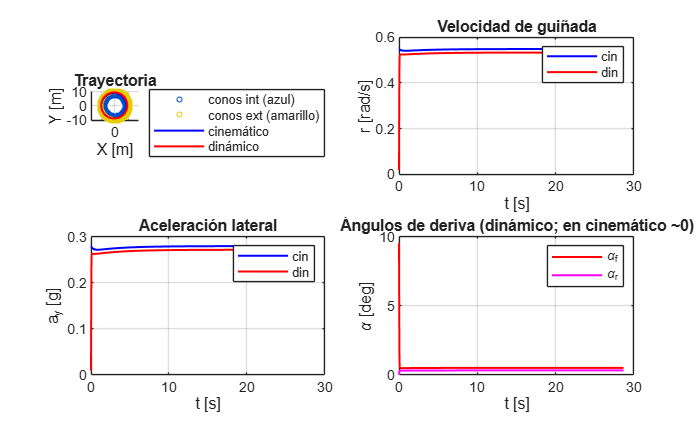

figure('Name','L2 · Skidpad','Color','w');

subplot(2,2,1); hold on; axis equal; grid on;  
  th = linspace(0,2*pi,200);
  plot(geom.R_in*cos(th), geom.R_in*sin(th), 'o','Color',[0 .3 .8],'MarkerSize',3);
  plot(geom.R_out*cos(th),geom.R_out*sin(th),'o','Color',[.9 .8 0],'MarkerSize',3);
  plot(histCin.X, histCin.Y, 'b-','LineWidth',1.2);
  plot(histDin.X, histDin.Y, 'r-','LineWidth',1.2);
  legend('inner cones (blue)','outer cones (yellow)','kinematic','dynamic','Location','bestoutside');
  title('Trajectory'); xlabel('X [m]'); ylabel('Y [m]');

subplot(2,2,2);   
  plot(histCin.t,histCin.r,'b', histDin.t,histDin.r,'r','LineWidth',1.2);
  ylabel('r [rad/s]'); xlabel('t [s]'); grid on; legend('cin','din');
  title('Yaw rate');

subplot(2,2,3);   
  plot(histCin.t, histCin.vx.*histCin.r/9.81,'b', ...
       histDin.t, histDin.vx.*histDin.r/9.81,'r','LineWidth',1.2);
  ylabel('a_y [g]'); xlabel('t [s]'); grid on; legend('cin','din');
  title('Lateral acceleration');

subplot(2,2,4);   
  plot(histDin.t, histDin.af*180/pi,'r', histDin.t, histDin.ar*180/pi,'m','LineWidth',1.2);
  ylabel('\alpha [deg]'); xlabel('t [s]'); grid on; legend('\alpha_f','\alpha_r');
  title('Slip angles (dynamic; approximately zero in kinematic)');

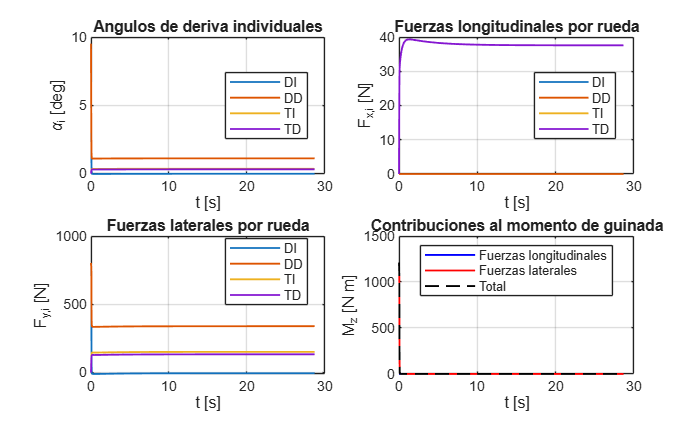


%% NEW FIGURE: four-wheel dynamic-model telemetry
% Wheel order: DI, DD, TI, TD. Original simulation is unchanged.
figure('Name','Four-wheel model - telemetry','Color','w');
nombres = {'DI','DD','TI','TD'};

subplot(2,2,1);
plot(histDin.t, rad2deg(histDin.alpha_w), 'LineWidth',1.1);
grid on; xlabel('t [s]'); ylabel('\alpha_i [deg]');
title('Individual slip angles'); legend(nombres,'Location','best');

subplot(2,2,2);
plot(histDin.t, histDin.Fxw, 'LineWidth',1.1);
grid on; xlabel('t [s]'); ylabel('F_{x,i} [N]');
title('Longitudinal forces per wheel'); legend(nombres,'Location','best');

subplot(2,2,3);
plot(histDin.t, histDin.Fyw, 'LineWidth',1.1);
grid on; xlabel('t [s]'); ylabel('F_{y,i} [N]');
title('Lateral forces per wheel'); legend(nombres,'Location','best');

subplot(2,2,4);
plot(histDin.t, histDin.Mz_long, 'b', ...
     histDin.t, histDin.Mz_lat, 'r', ...
     histDin.t, histDin.Mz_long + histDin.Mz_lat, 'k--', 'LineWidth',1.1);
grid on; xlabel('t [s]'); ylabel('M_z [N m]');
title('Yaw-moment contributions');
legend('Longitudinal forces','Lateral forces','Total','Location','best');

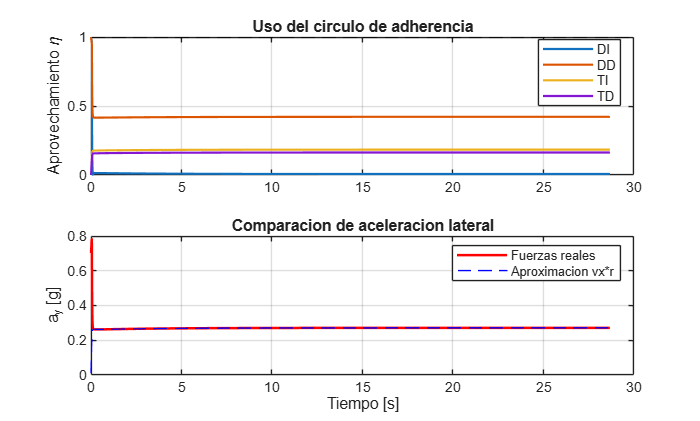

%% Friction-circle check

t = histDin.t(:);
Fx = histDin.Fxw;
Fy = histDin.Fyw;
Fz = histDin.Fzw;

% Adhesion utilization per wheel
Fmax = Fz .* p.muw;
eta = hypot(Fx, Fy) ./ Fmax;

% Lateral acceleration from forces
delta = atan((p.ld + p.lt)/geom.R);
delta_w = [delta, delta, 0, 0];

Fy_chasis = Fx.*sin(delta_w) + Fy.*cos(delta_w);
ay_real = sum(Fy_chasis, 2)/(p.m*p.g);

% Plots
figure('Color','w');

subplot(2,1,1)
plot(t, eta, 'LineWidth',1.3)
yline(1,'k--','Adhesion limit');
grid on;
ylabel('Utilization \eta');
legend('DI','DD','TI','TD','Location','best');
title('Friction-circle utilization');

subplot(2,1,2)
plot(t, ay_real, 'r','LineWidth',1.5)
hold on;
plot(t, histDin.vx(:).*histDin.r(:)/p.g, 'b--');
grid on;
xlabel('Time [s]');
ylabel('a_y [g]');
legend('Actual forces','Approximation vx*r');
title('Lateral-acceleration comparison');


% Numerical check
fprintf('Maximum utilization per wheel:\n');

Aprovechamiento maximo por rueda:


disp(max(eta,[],1));

    1.0000    1.0000    0.1839    0.1632




fprintf('Maximum lateral acceleration: %.3f g\n', ...
    max(abs(ay_real)));

Aceleracion lateral maxima: 0.784 g


fprintf('\n--- FOUR-WHEEL MODEL SUMMARY ---\n');


--- Resumen modelo 4 ruedas ---


fprintf('Final speed: %.2f m/s\n', histDin.vx(end));

Velocidad final: 5.00 m/s


fprintf('Final yaw rate: %.3f rad/s\n', histDin.r(end));

Guiñada final: 0.532 rad/s


fprintf('Max |slip angle| per wheel [deg]:');

Max |deriva| por rueda [deg]: 

fprintf('%.2f ', max(abs(rad2deg(histDin.alpha_w)),[],1));

9.52 9.52 0.35 0.30 

fprintf('\nMax |Fx| per wheel [N]:');


Max |Fx| por rueda [N]: 

fprintf('%.1f ', max(abs(histDin.Fxw),[],1));

0.0 0.0 39.3 39.3 

fprintf('\nMax |Fy| per wheel [N]:');


Max |Fy| por rueda [N]: 

fprintf('%.1f ', max(abs(histDin.Fyw),[],1));

803.8 803.8 151.0 132.8 

fprintf('\n');


The kinematic model follows a constant-radius circle without slip, while the dynamic model follows a slightly larger circle at the same steering angle because of understeer. The original exercise reports approximately 0.55 g lateral acceleration for both.

In Formula Student, skidpad time measures maximum lateral-acceleration performance. Automotive constant-radius tests also measure the understeer gradient.